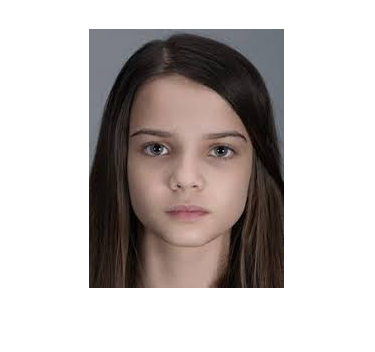


n = 3;
im = imageDatastore('photos\','IncludeSubfolders',true,'LabelSource','foldernames');
imshow(imread("photos\s01\test1.jpg"))

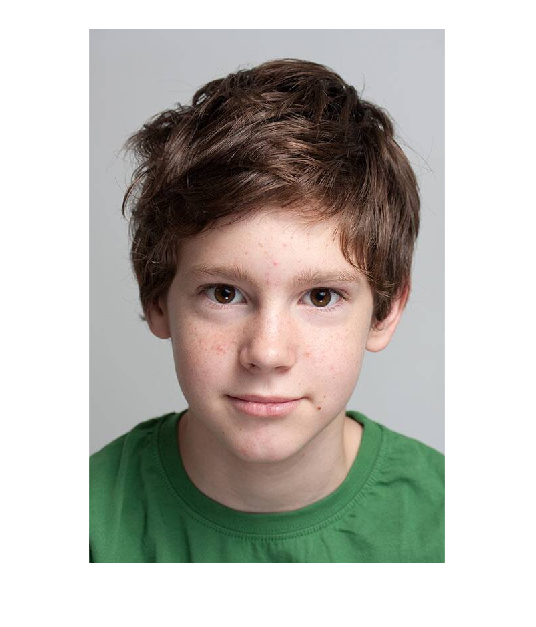

imshow(imread("photos\s02\test2.jpg"))

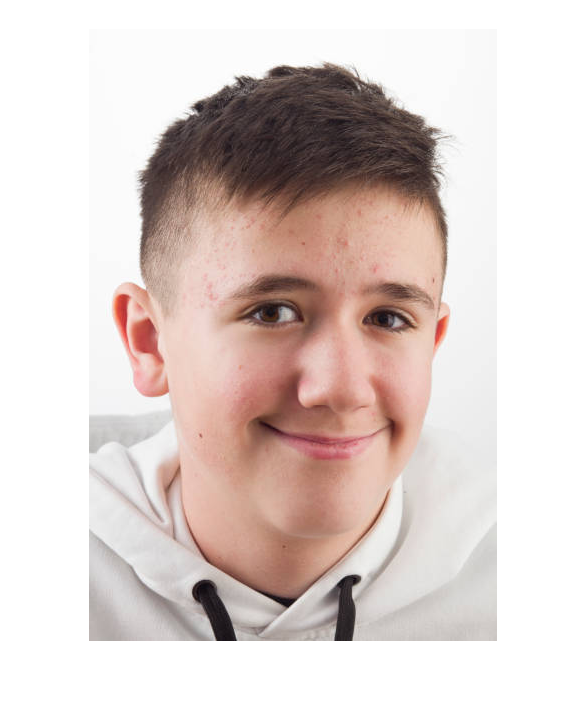

imshow(imread("photos\s03\test3.jpg"))


imdsTrain = splitEachLabel(im,0.8,'randomized');
net = alexnet;
inputSize = net.Layers(1).InputSize;
fc = fullyConnectedLayer(n); 
ly = net.Layers;
ly(23) = fc;
cl = classificationLayer;
ly(25) = cl; 

Train = augmentedImageDatastore(inputSize(1:2),imdsTrain);
learning_rate = 0.00001;
opts = trainingOptions("sgdm","InitialLearnRate",learning_rate,'MaxEpochs',5,'Plots','training-progress');
newnet = trainNetwork(Train, ly, opts);

Training on single CPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:25 |       66.67% |       2.6383 |      1.0000e-05 |


|       5 |           5 |       00:00:38 |       33.33% |       3.0050 |      1.0000e-05 |
|========================================================================================|


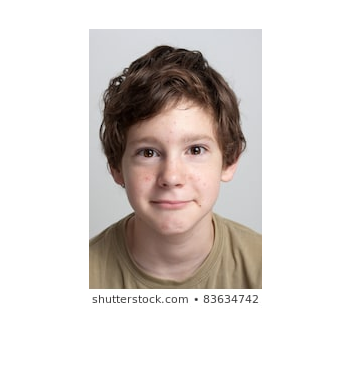

%test
img = imread('tst.jpg');
imshow(img)

img = imresize(img,[227 227]);
predict = classify(newnet,img);

nameofs01 = 'subject 1';
nameofs02 = 'subject 2';
nameofs03 = 'subject 3';

if predict=='s01'
  fprintf('The face detected is %s',nameofs01);
elseif  predict=='s02'
  fprintf('The face detected is %s',nameofs02);
elseif  predict=='s03'
  fprintf('The face detected is %s',nameofs03);
end	 

The face detected is subject 2